# Rotary Inverted Pendulum

## Motor Parameters

motor_b = 0.10692         ;   % Damping Coefficient
motor_j = 0.054058        ;   % System Inertia
motor_km = 0.68378        ;   % Motor speed constant
motor_kt = 4.1772         ;   % Motor Torque constant
motor_l = 0.00026447      ;   % Motor inductance
motor_r = 0.067034        ;   % Motor Resistance
motor_effeciency = 0.69   ;   % Motor effeciency
gear_box_effeciency = 0.9 ;   % Gearbox Effeciency
gear_box_ratio = 120      ;   % Motor gearbox ratio


## System Parameters


m_pendulum = 20/1000 ;  %the mass of pendulum in gram
r = 60/1000 ;           %length of arm in mm
l = (65/1000)/2;        %length of arm of pendulum in mm


## State Space Parameters

a=motor_j+(m_pendulum*r*r);
b=m_pendulum*l*r;
c=(4/3)*m_pendulum*l*l;
d=m_pendulum*9.8*l;

E=(a*c)-(b*b);
G = ((motor_effeciency*gear_box_effeciency*motor_km*motor_kt*(gear_box_ratio*gear_box_ratio))-(motor_b*motor_r))/(motor_r);

H= (motor_effeciency*gear_box_effeciency*motor_kt*gear_box_ratio)/(motor_r*E);


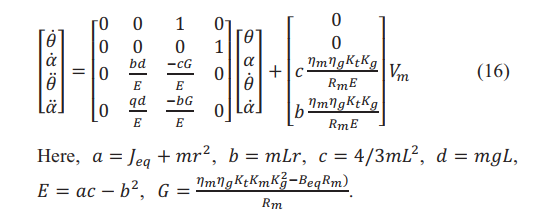

## State Space

A_mat=[0 0 1 0;0 0 0 1;0 (b*d)/(E) (-(c*G)/E) 0 ; 0 ((a*d)/E) (-b*G)/E 0 ]; % system matrix
B_mat=[0;0;(c)*(H);(b)*(H)];                                                % input matrix  
C_mat=[1 0 0 0 ; 0 1 0 0];                                                  % output matrix
D_mat=[0;0];                                                                % feedforward matrix

state_space_model=ss(A_mat,B_mat,C_mat,D_mat)                              % State space object

state_space_model =
 
  A = 
               x1          x2          x3          x4
   x1           0           0           1           0
   x2           0           0           0           1
   x3           0      0.1631  -7.046e+06           0
   x4           0       226.4  -9.756e+06           0
 
  B = 
              u1
   x1          0
   x2          0
   x3  8.587e+04
   x4  1.189e+05
 
  C = 
       x1  x2  x3  x4
   y1   1   0   0   0
   y2   0   1   0   0
 
  D = 
       u1
   y1   0
   y2   0
 
Continuous-time state-space model.


## LQR Parameters

q=diag([   1e-6     650      550         450      ]);
%      [   theta   alpha   thetadot   alphadot    ]
r_eq=1e-6;

k=lqr(state_space_model,q,r_eq);


k_theta=k(1)

k_theta = -1.0000

k_alpha=k(2)

k_alpha = 5.8170e+05

k_thetadot=k(3)

k_thetadot = -2.3534e+04

k_alphadot=k(4) 

k_alphadot = 4.4083e+04

## Step response

LQR_sys=ss(A_mat-B_mat*k,B_mat,C_mat,0)

LQR_sys =
 
  A = 
               x1          x2          x3          x4
   x1           0           0           1           0
   x2           0           0           0           1
   x3   8.587e+04  -4.995e+10   2.014e+09  -3.786e+09
   x4   1.189e+05  -6.917e+10   2.789e+09  -5.242e+09
 
  B = 
              u1
   x1          0
   x2          0
   x3  8.587e+04
   x4  1.189e+05
 
  C = 
       x1  x2  x3  x4
   y1   1   0   0   0
   y2   0   1   0   0
 
  D = 
       u1
   y1   0
   y2   0
 
Continuous-time state-space model.


TF = tf(LQR_sys)

TF =
 
  From input to output...
                  8.587e04 s^2 - 0.05776 s - 1.942e07
   1:  ---------------------------------------------------------
       s^4 + 3.228e09 s^3 + 6.917e10 s^2 + 4.554e11 s + 1.942e07
 
                 1.189e05 s^2 - 0.03541 s - 2.381e-06
   2:  ---------------------------------------------------------
       s^4 + 3.228e09 s^3 + 6.917e10 s^2 + 4.554e11 s + 1.942e07
 
Continuous-time transfer function.


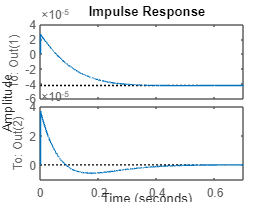

%step(TF)
impulse(LQR_sys)

## Poles & Zeros

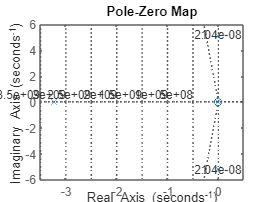

pzplot(TF(2))
grid on

pole(TF(2))

ans = 1.0e+09 *

  -3.2277 + 0.0000i
  -0.0000 + 0.0000i
  -0.0000 - 0.0000i
  -0.0000 + 0.0000i




%pole(TF(1))
%eig (A_mat)
%eig(A_mat-B_mat*k)

